# INPUTS

addpath(genpath('dependencies'));
% set default parameters (running script from Editor)
% if nargin == 0
N=128; S=3; n_thetas=7;
room = 'Balder'; % room choice: 'Munin','Freja','Balder'
u = 3;           % under-sampling ratio (integer)
tau = S;         % no. decomposition scales (2,...,5)
% nu_max = 15;     % thresholding iterations (positive integer)
saveFlag = 0;    % store data (true/false)
paretoFlag = 1; % change to 1 to actually calculate beta_star

## Prepara imagen

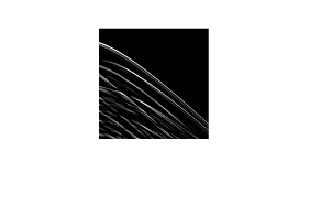

% load image
[image,imSize,~,epsilon] = loadRIRs(room,u);
figure;
imshow(image(1:100, :))


% Mis boostlets son de MxM no de TxM
% No le doy la imagen grande TxM si no una subimagen
% de tamaño MxM.
% Si extrapolo la imagen, es solo en columnas por lo que tendre
% una imagen de 100x 128, por lo que mi subimagen debe ser de 128x100
% para que al extrapolar, obtenga 128x128.
start = 1; M = min(imSize);
imSize = [128,M];
image = image(start:start+imSize(1)-1, imSize(2));

% mask image, lambda es la mascara que da los samples verdaderos o
% seleccionados, ranPos es un vector con las columnas elegidas
[lambda,ranPos,~] = selectionMtrx(u,imSize);
size(lambda)

ans =    128   100


size(ranPos)

ans =     33     1


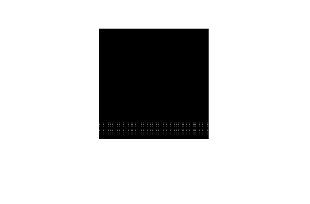


% imagen con mascara
image_under = lambda.*image; 
figure;
imshow(image_under(1:100, :))


% extrapolate image & sparse matrix with diagonal with true samples
[image_under,imSize,~,LAMBDA,origAprtr] = ...
    extRIRimage(image_under,lambda,ranPos);

size(image_under)

ans =    128   128


size(LAMBDA)

ans =         4224       16384


3623*128

ans = 463744

lambda es una matriz de tamaño m*n que es la mascara aplicada a la imagen original

image_under = lambda*imagen es la imagen con columnas eliminadas.

image_under es extrapolada con el mismo numero de columnas por la izquierda y la derecha. 

lambda también es ampliada con ones() para esas columnas extrapoladas.

LAMBDA es una matriz sparse. En su diagonal pone lambda puesto como vector por orden de columnas. Se le  eliminan despues las filas que corresponden a los elementos de lambda con elementos "falsos" (los enmascarados y los extrapolados). Se conservan solo las filas que corresponden a samples "verdaderos". Si lambda es (m,n), entonces LAMBDA primero es (m*n, m*n) y luego se eliminan las filas de elementos falsos pasando a ser de (LAM_rows, m*n) con LAM_rows < m*n.

% matrix-vector masking of observations
y_hat = LAMBDA*image_under(:);
size(y_hat)

ans =         4224           1


## Shearlets verticales que se eliminan.

Necesario para boostlets? 

En cuyo caso, qué tau se usaría?

Habría que eliminar los mismos indices de los boostlets?

% expansion matrix (remove vertical-like shearlets)
% E = expansionMtrx(imSize,tau);
E = expansionMtrx_boost(imSize, S, n_thetas);


## Cargar funciones base

% load(['basisFunctions/' room '_tau' num2str(tau) '.mat'],'Psi');
% N=128; S=2; n_thetas=7;
filename = sprintf('boostlets_N_%i_S_%i_thetas_%i.mat', N, S, n_thetas)

filename = 'boostlets_N_128_S_3_thetas_7.mat'

load(['basisFunctions/' filename],'Psi'); 
Sk = Psi;
size(Psi)

ans =    128   128    43


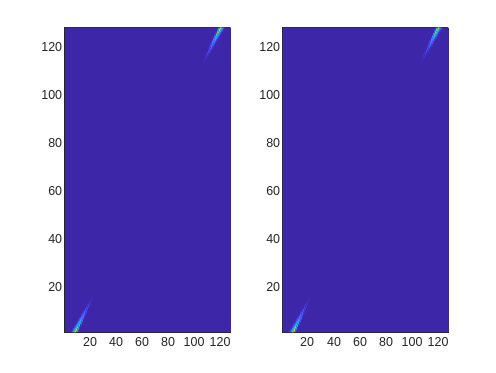

iboost = 8;
figure; 
subplot(1,2,1); pcolor(real(Psi(:,:,iboost))); shading interp;
subplot(1,2,2); pcolor(imag(Psi(:,:,iboost))); shading interp;

## Threshold para la optimizacion:

Necesito E (que son los boostlets que elimino)


Finding optimal Pareto point...
Pareto iteration 1/50.
Pareto iteration 2/50.
Pareto iteration 3/50.
Pareto iteration 4/50.
Pareto iteration 5/50.
Pareto iteration 6/50.
Pareto iteration 7/50.
Pareto iteration 8/50.
Pareto iteration 9/50.
Pareto iteration 10/50.
Pareto iteration 11/50.
Pareto iteration 12/50.
Pareto iteration 13/50.
Pareto iteration 14/50.
Pareto iteration 15/50.
Pareto iteration 16/50.
Pareto iteration 17/50.
Pareto iteration 18/50.
Pareto iteration 19/50.
Pareto iteration 20/50.
Pareto iteration 21/50.
Pareto iteration 22/50.
Pareto iteration 23/50.
Pareto iteration 24/50.
Pareto iteration 25/50.
Pareto iteration 26/50.
Pareto iteration 27/50.
Pareto iteration 28/50.
Pareto iteration 29/50.
Pareto iteration 30/50.
Pareto iteration 31/50.
Pareto iteration 32/50.
Pareto iteration 33/50.
Pareto iteration 34/50.
Pareto iteration 35/50.
Pareto iteration 36/50.
Pareto iteration 37/50.
Pareto iteration 38/50.
Pareto iteration 39/50.
Pareto iteration 40/50.
Pareto iteration

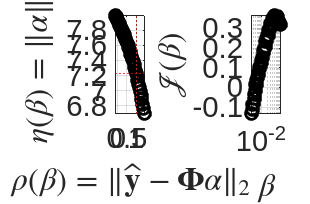

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%             CHOOSING THRESHOLD            %%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if ~paretoFlag
    load(['regularizationData/' room '_u' num2str(u) '_tau' ...
          num2str(tau) '.mat'],'reguThresh');
    beta_star = reguThresh.beta_star;
else
    [beta_star,Jcurve,beta_set] = computePareto(y_hat,LAMBDA,E,imSize,Sk);
end

% alpha0 = E'*ffst(LAMBDA'*y_hat,imSize,Sk);  % initialize solution vector
size(y_hat)
size(LAMBDA)
LAMBDA'*y_hat

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%               ISTA RECOVERY               %%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tic; alpha = ista(y_hat,LAMBDA,E,nu_max,imSize,Sk,beta_star,epsilon); 
CT = toc; % estimate computation time (CT)
fprintf('\n    >> Computation time (CT): %3.1f minutes\n',CT/60);
% recover inpainted image from sparse coefficients (Eq. 19)
image_recov = reshape(iffst(E*alpha,imSize,Sk),imSize);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%            PERFORMANCE METRICS            %%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[NMSE,MAC,frqMAC] = perforMetrics(image,image_recov(:,origAprtr),...
                                  image_under(:,origAprtr));
fprintf('-----------------------------------------------------\n');
fprintf('-----------------------------------------------------\n');
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%               STORE RESULTS               %%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if saveFlag
    if paretoFlag % only if computePareto runs...
        % regularization data...
        reguThresh.beta_star = beta_star;
        reguThresh.Jcurve    = Jcurve;
        reguThresh.beta_set  = beta_set;
        save(['regularizationData/' room '_u' num2str(u) '_tau' ...
              num2str(tau) '.mat'],'reguThresh');
    end
	% interpolation results...
    if ~exist(['results/' room],'dir')
        mkdir(['results/' room]);
    end
    results.NMSE = NMSE;
    results.MAC = MAC;
    results.frqMAC = frqMAC;
    results.image = image;
    results.image_recov = image_recov(:,origAprtr);
    results.image_under = image_under(:,origAprtr);
    save(['results/' room '/u' num2str(u) 'tau' num2str(tau) '.mat'],'results');
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%                END CODE...                %%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% remove dependencies...
rmpath(genpath('dependencies'));
% end